## Results

This script contains the nonlinear simulation of the synthesised state feedback and static output feedback controller. 

### Statefeedback controller 

synthesize a controller with a setteling time of 10 min. 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

### Filter

The controller is designed with only Wref, Wu =0  and Dwz = 20I_4

%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

param.model.Dwz = 20*eye(4);

### Synthesise controller

param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.229495 


### Simulate non-linear response

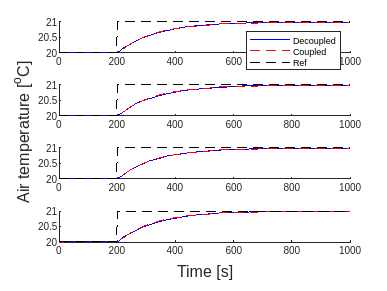

util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults",0,1000);

synthesize a controller with a setteling time of 1 min. 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

### Filter

The controller is designed with only Wref, Wu =0  and Dwz = 20I_4

%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(12*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

param.model.Dwz = 20*eye(4);

### Synthesise controller

param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.239520 


### Simulate non-linear response

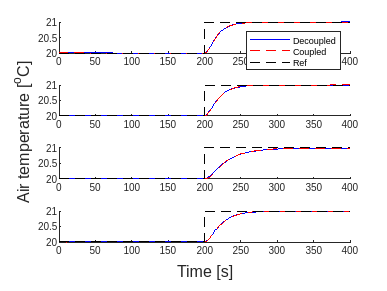

util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_1_min",0,400);

### Static output feedback